# For general g1=(C+iD) and than g2=(A+iB)

**Step 1 - choose your lattice:**

clear all;
plot_full_wigner = 1 ;

m=0 ; n=0; k=0; l=0; r=0;

row = 7 ;
% g1 for C and D. acts first. g2 for A and B.

t1=0;t2=0;

switch row
    case 1
        t1=0;t2=0;
        g1 = 0.5*sqrt(pi/2)*exp(1i*t1); g2 = 0.5*1i*sqrt(pi/2)*exp(1i*t1) ;r=6; m=2*r ; k=2*r ; % Row 1. for normal |0>
    case 2
        t1=0;t2=0;
        g1 = 0.5*1i*sqrt(pi/2); g2 = sqrt(pi/2) ;r=3; m=r ; n=0; k=4*r; l=0; % Row 2.
    case 3
        t1=0;t2=0;
        g1 = 1i*sqrt(pi/2); g2 = sqrt(pi/2) ;r=3; m=r ; n=0; k=r ; l=0; % Row 3.
    case 4
        t1=0;t2=0;
        g1 = 0.25*1i*sqrt(pi/2); g2 = 0.25*sqrt(pi/2) ;r=12; m=2*r; n=2*r ; k=4*r ;l=0; % Row 4.
    case 5
         t1=0;t2=0;
        r=1 ; m=3*r; n=0; theta = pi; g=sqrt(pi/2) ; g1=g; g2=1;
        Prob_squeezed_rec = calculate_squeezed_vacuum_prob_analytical(m,n,1.1513,theta,g) ;
    case 6 % hexagonal 0
        t1=-pi/6;t2=-pi/3;
        
        g1=0.5*sqrt(pi/sqrt(3));              g2  =0.5*sqrt(pi/sqrt(3))*exp(1i*2*pi/3); l=0; % Row 6. Hexagonal GKP
        g1t1=0.5*sqrt(pi/sqrt(3))*exp(1i*t1); g2t1=0.5*sqrt(pi/sqrt(3))*exp(1i*2*pi/3)*exp(1i*t1); % Row 6. Hexagonal GKP
        g1t2=0.5*sqrt(pi/sqrt(3))*exp(1i*t2); g2t2=0.5*sqrt(pi/sqrt(3))*exp(1i*2*pi/3)*exp(1i*t2); % Row 6. Hexagonal GKP
        r=8 ; m=2*r; n=0; k=2*r; 
    
    case 7 % magic
        t1=-pi/6;t2=-pi/3;
        
        g1=sqrt(pi/sqrt(3))*exp(1i*2*pi/3);              g2=sqrt(pi/sqrt(3));
        g1t1=sqrt(pi/sqrt(3))*exp(1i*2*pi/3)*exp(1i*t1); g2t1=sqrt(pi/sqrt(3))*exp(1i*t1);
        g1t2=sqrt(pi/sqrt(3))*exp(1i*2*pi/3)*exp(1i*t2); g2t2=sqrt(pi/sqrt(3))*exp(1i*t2);
        r=6 ; m=r; n=0; k=r; l=0; % Row 7. Hexagonal GKP from vacuum
    case 8
        r=1 ; m=3*r; n=0; g=sqrt(pi/sqrt(3)); theta = 4*pi/3; 
        g1=g; g2=1;
        Prob_squeezed_hex = calculate_squeezed_vacuum_prob_analytical(m,n,0.6857,theta,g) 
end

zticks_vec = [-1 0 1 2]  ; offset = -0.3 ; 
xy_lim= 4*sqrt(pi); 
% theta2 = pi/2 + 2*pi/3 ; %to calculate the squeezing on another axis
% theta1 = pi/2 + pi/3 ; %to calculate the squeezing on another axis
% theta2 = pi/2 + pi/3 ; %to calculate the squeezing on another axis
% theta1 = pi/3  ; %to calculate the squeezing on another axis



`psi(x)`**, **`psi(p)`**, **`psi(v)`** for general v:**

% theta1 =pi/4 ; %30
% theta2 = 3*pi/4 ; %90+60=150

lim = 6*sqrt(pi) ;
resolution = 1e-4;
p=-lim:resolution:lim;
x=-lim:resolution:lim;

psi_x=0;
psi_p=0;
for a=0:m
    for b=0:n
        for c=0:k
            for d=0:l
                A=(2*a+2*b-m-n)*real(g2) ; B=(2*a+2*b-m-n)*imag(g2) ; 
                C=(2*c+2*d-k-l)*real(g1) ; D=(2*c+2*d-k-l)*imag(g1) ;

                psi_x=psi_x+nchoosek(m,a)*nchoosek(n,b)*nchoosek(k,c)* nchoosek(l,d)*((-1)^(b+d))*...
                   exp(-1i*(A*D-B*C) + 1i*(B+D)*(A+C) + 1i* sqrt(2)*(B+D).*(x-sqrt(2)*(A+C))).*...
                   exp(-0.5.*(x-sqrt(2)*(A+C)).^2);
                

                psi_p=psi_p+nchoosek(m,a)*nchoosek(n,b)*nchoosek(k,c)* nchoosek(l,d)*((-1)^(b+d))*...
                   exp(-1i*(A*D-B*C) + 1i*(B+D)*(A+C) - 1i* sqrt(2)*(A+C).*p).* exp(-0.5.*(p+sqrt(2)*(B+D)).^2);

            end
        end
    end
end

if t1 ~= 0 
   
    psi_xt1=0;
    psi_pt1=0;
    for a=0:m
        for b=0:n
            for c=0:k
                for d=0:l
                    A=(2*a+2*b-m-n)*real(g2t1) ; B=(2*a+2*b-m-n)*imag(g2t1) ; 
                    C=(2*c+2*d-k-l)*real(g1t1) ; D=(2*c+2*d-k-l)*imag(g1t1) ;
    
                    psi_xt1=psi_xt1+nchoosek(m,a)*nchoosek(n,b)*nchoosek(k,c)* nchoosek(l,d)*((-1)^(b+d))*...
                       exp(-1i*(A*D-B*C) + 1i*(B+D)*(A+C) + 1i* sqrt(2)*(B+D).*(x-sqrt(2)*(A+C))).*...
                       exp(-0.5.*(x-sqrt(2)*(A+C)).^2);
                    
                    psi_pt1=psi_pt1+nchoosek(m,a)*nchoosek(n,b)*nchoosek(k,c)* nchoosek(l,d)*((-1)^(b+d))*...
                       exp(-1i*(A*D-B*C) + 1i*(B+D)*(A+C) - 1i* sqrt(2)*(A+C).*p).* exp(-0.5.*(p+sqrt(2)*(B+D)).^2);
    
                end
            end
        end
    end
end

if t2 ~= 0 
    psi_xt2=0;
    psi_pt2=0;
    for a=0:m
        for b=0:n
            for c=0:k
                for d=0:l
                    A=(2*a+2*b-m-n)*real(g2t2) ; B=(2*a+2*b-m-n)*imag(g2t2) ; 
                    C=(2*c+2*d-k-l)*real(g1t2) ; D=(2*c+2*d-k-l)*imag(g1t2) ;
    
                    psi_xt2=psi_xt2+nchoosek(m,a)*nchoosek(n,b)*nchoosek(k,c)* nchoosek(l,d)*((-1)^(b+d))*...
                       exp(-1i*(A*D-B*C) + 1i*(B+D)*(A+C) + 1i* sqrt(2)*(B+D).*(x-sqrt(2)*(A+C))).*...
                       exp(-0.5.*(x-sqrt(2)*(A+C)).^2);

    
                    psi_pt2=psi_pt2+nchoosek(m,a)*nchoosek(n,b)*nchoosek(k,c)* nchoosek(l,d)*((-1)^(b+d))*...
                       exp(-1i*(A*D-B*C) + 1i*(B+D)*(A+C) - 1i* sqrt(2)*(A+C).*p).* exp(-0.5.*(p+sqrt(2)*(B+D)).^2);
    
                end
            end
        end
    end
end
% here I use the notation psi_0 =psi_x  psi_90 =psi_p

psi_x_2 = (abs(psi_x)).^2 ;
psi_p_2 = (abs(psi_p)).^2 ;
norm_x = trapz(x,psi_x_2,2) 

norm_x = 1.7034e+06

norm_p = trapz(p,psi_p_2,2) 

norm_p = 1.7102e+06

psi_x_2 = psi_x_2 / norm_x ;
psi_p_2 = psi_p_2 / norm_p ;

if t1 ~= 0 
    psi_30_2 = (abs(psi_xt1)).^2 ;
    psi_120_2 = (abs(psi_pt1)).^2 ;
    norm_x = trapz(x,psi_30_2,2) 
    norm_p = trapz(p,psi_120_2,2)
    psi_30_2 = psi_30_2 / norm_x ;
    psi_120_2 = psi_120_2 / norm_p ;
end

norm_x = 1.7102e+06

norm_p = 1.7034e+06


if t2 ~= 0 
    psi_60_2 = (abs(psi_xt2)).^2 ;
    psi_150_2 = (abs(psi_pt2)).^2 ;
    norm_x = trapz(x,psi_60_2,2) 
    norm_p = trapz(p,psi_150_2,2) 
    psi_60_2 = psi_60_2 / norm_x ;
    psi_150_2 = psi_150_2 / norm_p ;
end

norm_x = 1.7104e+06

norm_p = 1.6970e+06

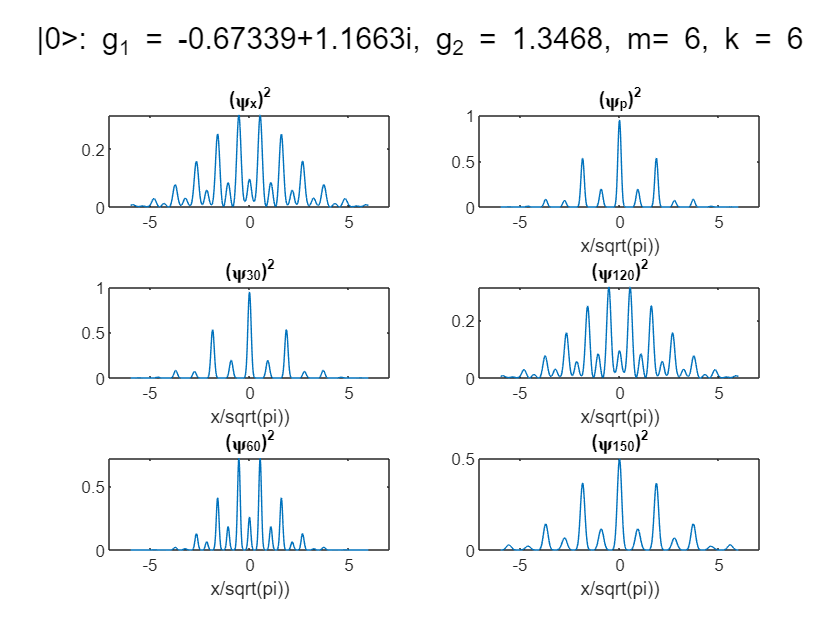



figure(1) ; sgtitle(strcat("|0>: g_1 = ",num2str(g1),", g_2 = ", num2str(g2), ", m= ", num2str(m), ", k = ", num2str(k)))
subplot(3,2,1) ; plot(x/sqrt(pi),psi_x_2) ;
xlim ([-xy_lim, xy_lim]) ;  title("(\psi_x)^2") ; 
subplot(3,2,2) ; plot(x/sqrt(pi),psi_p_2);
xlim ([-xy_lim, xy_lim]) ;  title("(\psi_p)^2") ;   xlabel("x/sqrt(pi))") ;


if t1 ~= 0 
    subplot(3,2,3) ; plot(x/sqrt(pi),psi_30_2);
    xlim ([-xy_lim, xy_lim]) ;  title("(\psi_{30})^2") ;   xlabel("x/sqrt(pi))") ;
    subplot(3,2,4) ; plot(x/sqrt(pi),psi_120_2);
    xlim ([-xy_lim, xy_lim]) ;  title("(\psi_{120})^2") ;   xlabel("x/sqrt(pi))") ;

end

if t2 ~= 0 
    subplot(3,2,5) ; plot(x/sqrt(pi),psi_60_2);
    xlim ([-xy_lim, xy_lim]) ;  title("(\psi_{60})^2") ;   xlabel("x/sqrt(pi))") ;
    subplot(3,2,6) ; plot(x/sqrt(pi),psi_150_2);
    xlim ([-xy_lim, xy_lim]) ;  title("(\psi_{150})^2") ;   xlabel("x/sqrt(pi))") ;

end

**Probabilities and plot wigner:**

num_of_even_g_steps = m; num_of_even_ig_steps=k; num_of_odd_g_steps=n; num_of_odd_ig_steps=l;


steps = create_steps(num_of_even_g_steps,num_of_odd_g_steps,num_of_even_ig_steps,num_of_odd_ig_steps) ;
[L_list,Coe_list] = make_cat_lattice(steps,g1,g2,2) ;
%print_state_2D(L_list,Coe_list,g1,g2)
norm_pow2 = calculate_norm_list(L_list,Coe_list,L_list,Coe_list) %calculate <psi|psi>

norm_pow2 = 9.6498e+05 + 3.8930e-18i

Elapsed time is 7.325226 seconds.


int_check = 0.9953 - 0.0000i

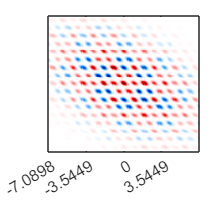

Coe_list = Coe_list / sqrt(real(norm_pow2)) ; %normalization

plot_full_wigner=1;
if plot_full_wigner ==1
    [W,x_wigner,p_wigner] = calculate_Wigner(lim,L_list,Coe_list);
    plot_Wigner_only_imagesc(p_wigner,x_wigner,W,offset,zticks_vec,xy_lim);
    int_check = trapz(x_wigner,trapz(p_wigner,W,2)) % if it is not 1, you need to increase lim
    set(gcf,'units','points','position',[0,0,110,100]) ;
    set(gca,'XTick',[-4*sqrt(pi),-2*sqrt(pi), 0,2*sqrt(pi)],'YTick',[]) ;
end


prob = 100*nchoosek(k+l,k)*nchoosek(m+n,m)*real(norm_pow2) / (4^(m+n+k+l)) %in precentages

prob = 5.7517


lim = 6*sqrt(pi) ;
resolution = 1e-4;
[W_x,x_i] = calculate_psi_x(lim,L_list,Coe_list,resolution);

Elapsed time is 0.371353 seconds.


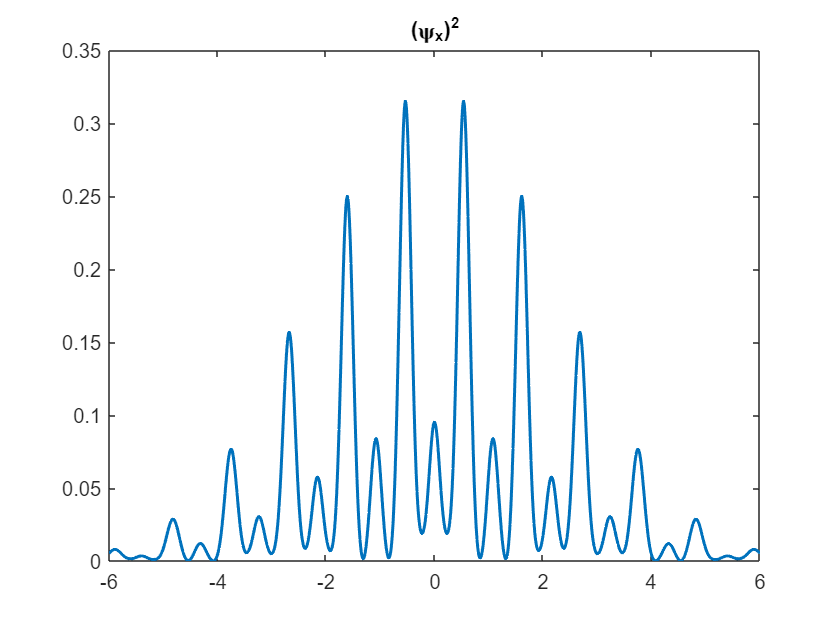

figure() ;
plot(x_i/sqrt(pi),W_x,'DisplayName','Gaussian','LineWidth',1.5);  title("(\psi_x)^2") ; 


[W_p,p_i] = calculate_psi_p(lim,L_list,Coe_list,resolution);

Elapsed time is 0.424079 seconds.


figure() ;
plot(p_i/sqrt(pi),W_p,'DisplayName','Gaussian','LineWidth',1.5); title("(\psi_p)^2") ; 

theta1 = 0; theta2=0;
W_v1 = ((cos(theta1))^2)*real(W_x) + ((sin(theta1))^2)*real(W_p);
norm_v = trapz(x_i,W_v1,2)  %should be 1

norm_v = 1.0000

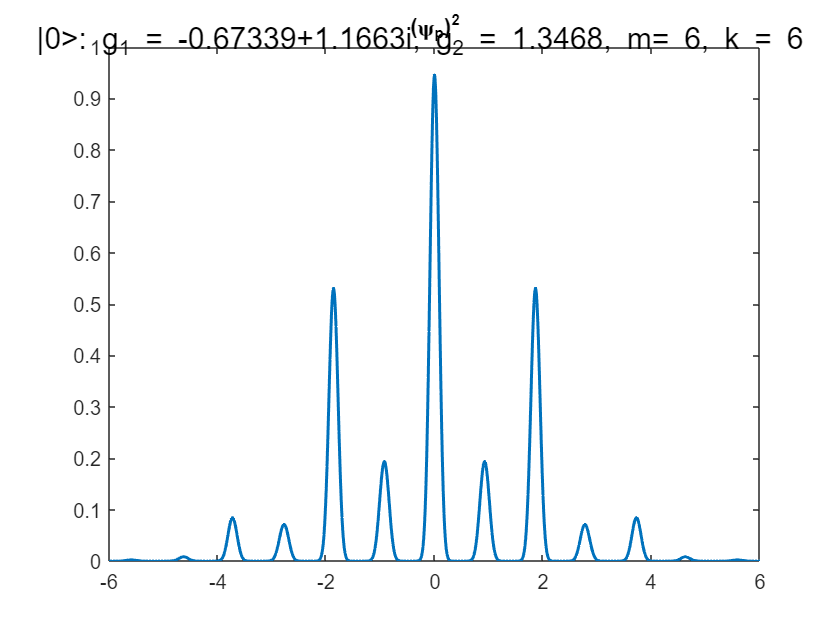

W_v2 = ((cos(theta2))^2)*real(W_x) + ((sin(theta2))^2)*real(W_p);

figure(2) ; sgtitle(strcat("|0>: g_1 = ",num2str(g1),", g_2 = ", num2str(g2), ", m= ", num2str(m), ", k = ", num2str(k)))

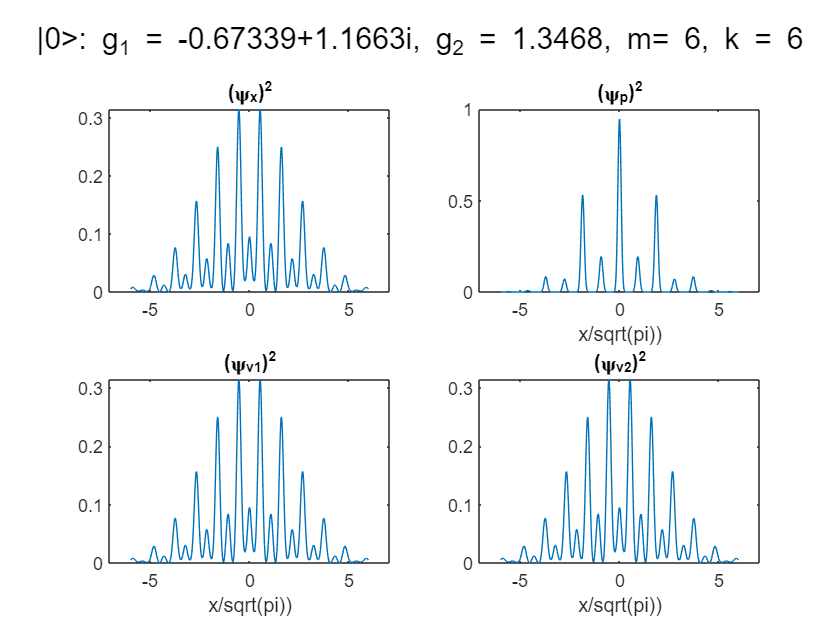

subplot(2,2,1) ; plot(x_i/sqrt(pi),W_x) ;
xlim ([-xy_lim, xy_lim]) ;  title("(\psi_x)^2") ; 
subplot(2,2,2) ; plot(x_i/sqrt(pi),W_p);
xlim ([-xy_lim, xy_lim]) ;  title("(\psi_p)^2") ;   xlabel("x/sqrt(pi))") ;
subplot(2,2,3) ; plot(x_i/sqrt(pi),W_v1);
xlim ([-xy_lim, xy_lim]) ;  title("(\psi_{v1})^2") ;   xlabel("x/sqrt(pi))") ;
subplot(2,2,4) ; plot(x_i/sqrt(pi),W_v2);
xlim ([-xy_lim, xy_lim]) ;  title("(\psi_{v2})^2") ;   xlabel("x/sqrt(pi))") ;

**Find squeezing parameter numericly:**

s_x = min(find_squeezing(x,real(psi_x_2)))

s_x = 0.0713

s_p = min(find_squeezing(x,real(psi_p_2)))

s_p = 0.0430

s_30 = min(find_squeezing(x,real(psi_30_2)))

s_30 = 0.0430

s_120 = min(find_squeezing(x,real(psi_120_2)))

s_120 = 0.0713

s_60 = min(find_squeezing(x,real(psi_60_2)))

s_60 = 0.0281

s_150 = min(find_squeezing(x,real(psi_150_2)))

s_150 = 0.0764

squeeing_x   = -10*log10(s_x)

squeeing_x = 11.4695

squeeing_p   = -10*log10(s_p)

squeeing_p = 13.6624

squeeing_30  = -10*log10(s_30)

squeeing_30 = 13.6624

squeeing_120 = -10*log10(s_120)

squeeing_120 = 11.4695

squeeing_60  = -10*log10(s_60)

squeeing_60 = 15.5105

squeeing_150 = -10*log10(s_150)

squeeing_150 = 11.1699



% for 10dB we need 0.1. of s<0.1 --> more than 10dB, good


% %should be the same:
% s_1 = min(find_squeezing(x_i,W_x,epsilon))  % if its empty, increase epsilon
% s_2 = min(find_squeezing(p_i,W_p,epsilon))  % if its empty, increase epsilon


% For square lattice, starting from a vacuum state - analytical formula for squeezing: (row 2,3 in the
% table)
s_x_theory = 1/(1+2*(abs(g1)^2)*k)

s_x_theory = 0.0439

s_p_theory = 1/(1+2*(abs(g2)^2)*m)

s_p_theory = 0.0439

squeezing_x = -10*log10(s_x_theory)

squeezing_x = 13.5728

squeezing_y= -10*log10(s_p_theory)

squeezing_y = 13.5728


%% starting from a squeezed state:
% For square lattice, starting from a squeezed vacuum state - analytical formula for squeezing: (row 5,8 in the
% table)
%row 5 - square GKP:
%m=3
s_x_theory = 1/10  % Delta^2

s_x_theory = 0.1000

s_p_theory = 10/(1+10*pi*m)  % Delta^2

s_p_theory = 0.0528

r=1.1513 ; theta=pi; m=3; g=sqrt(pi/2) ;
delta_x = real((1-exp(1i*2*theta)*tanh(r))/(1+exp(1i*2*theta)*tanh(r)))

delta_x = 0.1000

delta_p = 1/(real(  (1-exp(1i*2*theta)*tanh(r))/(1+exp(1i*2*theta)*tanh(r)) +2*(g^2)*m ))

delta_p = 0.1050


squeeing_x = -10*log10(delta_x)

squeeing_x = 10.0001

squeeing_p = -10*log10(delta_p)

squeeing_p = 9.7885



%row 8 - hexagonal GKP:
s_x_theory = 1/10  % Delta^2

s_x_theory = 0.1000

s_p_theory = sqrt(3)*10/(sqrt(3)+2*10*pi*m)  % Delta^2

s_p_theory = 0.0911

r=0.6857 ; theta=4*pi/3; m=3; g=sqrt(pi/sqrt(3)) ;
delta_x = real((1-exp(1i*2*theta)*tanh(r))/(1+exp(1i*2*theta)*tanh(r))) % not interesting here, we need delta_v

delta_x = 0.8507

delta_p = 1/(real(  (1-exp(1i*2*theta)*tanh(r))/(1+exp(1i*2*theta)*tanh(r)) +2*(g^2)*m ))

delta_p = 0.0852


squeeing_x = -10*log10(delta_x)

squeeing_x = 0.7023

squeeing_p = -10*log10(delta_p)

squeeing_p = 10.6943

% starting 

% plot(x_i/sqrt(pi),W_x,'DisplayName','W(x)','LineWidth',1.5);  title("(\psi_x)^2") ; 
% hold on
% plot(x/sqrt(pi),psi_x_2,'LineWidth',1.5) ;
% hold off
% legend()



